# Experiment1

## continuous square wave

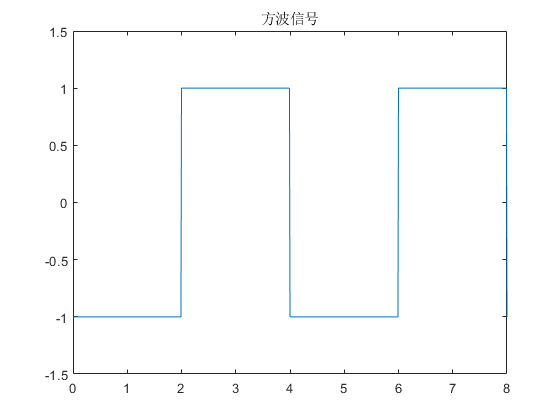

k = 1.6;
max_order = 501;
t = 0:0.01:5*k;
square_fourier = zeros([(max_order+1)/2, 500*k+1]);
squarew = square_wave(t);

for i = 1:500*k+1
    for j = 1:(max_order+1)/2
        square_fourier(j, i) = -(4/((2*j-1)*pi))*sin((2*j-1)*pi*0.01*i/2);
    end
end

figure;
plot(t, squarew);

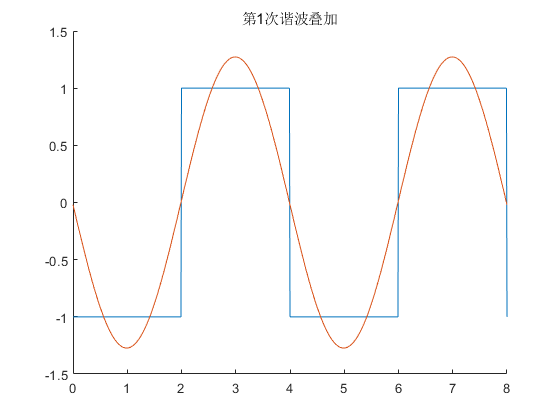

ylim([-1.5, 1.5]);
title("方波信号");

figure; hold on; 

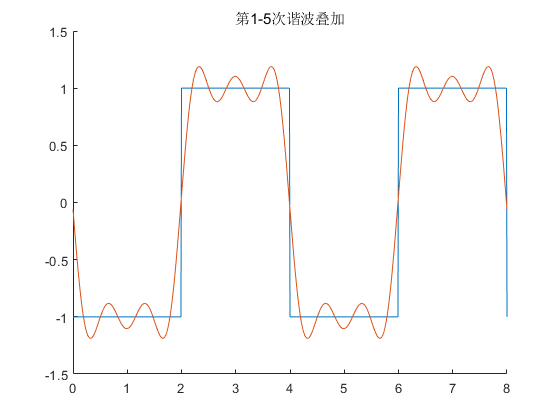

plot(t, squarew);
plot(t, square_fourier(1, :));
title("第1次谐波叠加"); 
hold off;

figure; hold on;

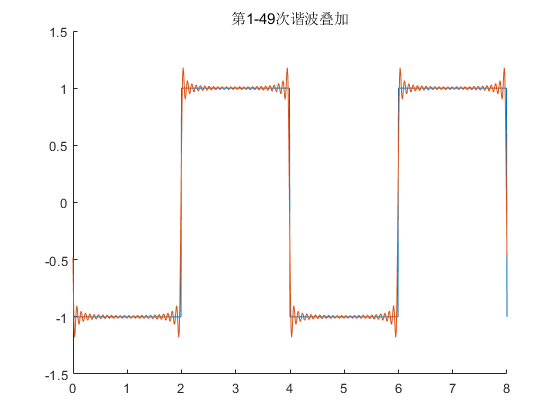

plot(t, squarew);
plot(t, sum(square_fourier(1:3, :), 1));
title("第1-5次谐波叠加");
hold off;

figure; hold on;

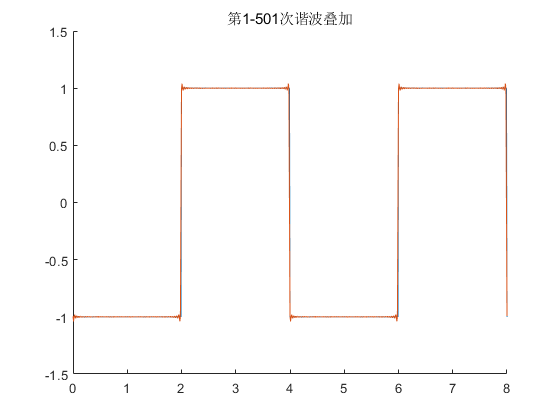

plot(t, squarew);
plot(t, sum(square_fourier(1:25, :), 1));
title("第1-49次谐波叠加");
hold off;

figure; hold on;

plot(t, squarew);
plot(t, sum(square_fourier, 1));
title("第1-501次谐波叠加");
hold off;

## discrete square wave

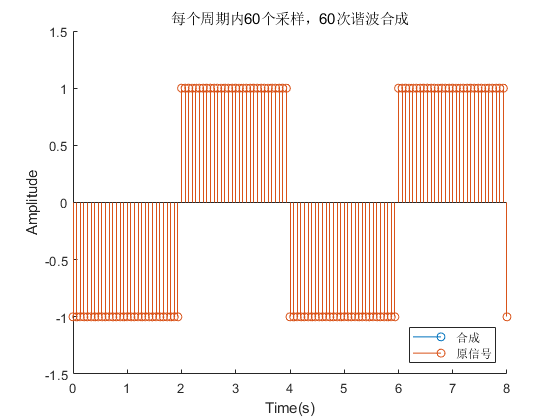

T = 4;
T_len = 8;
N1 = 60;
N2 = 120;
max_order = 60;
dfs1 = zeros(N1, (T_len/T)*N1);
dfs2 = zeros(N2, (T_len/T)*N2);
sample1 = square_wave(0:(T/N1):T_len);
sample2 = square_wave(0:(T/N2):T_len);
a_k1 = zeros([1, N1]);
b_k1 = zeros([1, N1]);
a_k2 = zeros([1, N2]);
b_k2 = zeros([1, N2]);

for i = 0:N1-1
    a_k1(i+1) = sample1(1:N1) * cos(2*pi*i/N1 * (0:N1-1))' ./ N1;
    b_k1(i+1) = - sample1(1:N1) * sin(2*pi*i/N1 * (0:N1-1))' ./ N1;
end
for k = 0:N1-1
    for n = 0:(T_len/T)*N1
        dfs1(k+1, n+1) = a_k1(k+1) * cos(2*pi*k*n/N1) - b_k1(k+1) * sin(2*pi*k*n/N1);
    end
end

for i = 0:N2-1
    a_k2(i+1) = sample2(1:N2) * cos(2*pi*i/N2 * (0:N2-1))' ./ N2;
    b_k2(i+1) = - sample2(1:N2) * sin(2*pi*i/N2 * (0:N2-1))' ./ N2;
end
for k = 0:N2-1
    for n = 0:(T_len/T)*N2
        dfs2(k+1, n+1) = a_k2(k+1) * cos(2*pi*k*n/N2) - b_k2(k+1) * sin(2*pi*k*n/N2);
    end
end

figure;
hold on;
stem(0:(T/N1):T_len, sum(dfs1(1:max_order, :), 1));
stem(0:(T/N1):T_len, sample1);
xlabel("Time(s)");
ylabel("Amplitude");
title("每个周期内60个采样，60次谐波合成");
legend(["合成", "原信号"],  "Location", "southeast");
hold off;

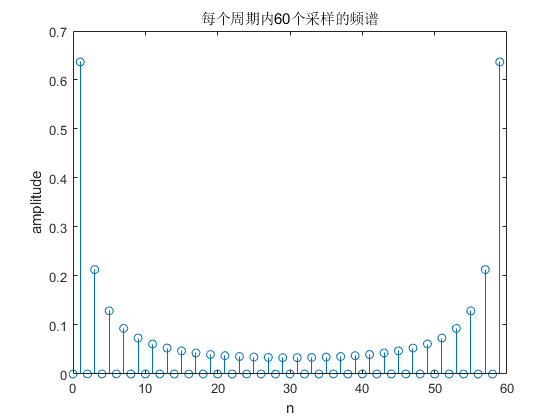


figure;
stem(0:N1-1, sqrt(a_k1.^2 + b_k1.^2));
title("每个周期内60个采样的频谱");
xlabel("n");
ylabel("amplitude");

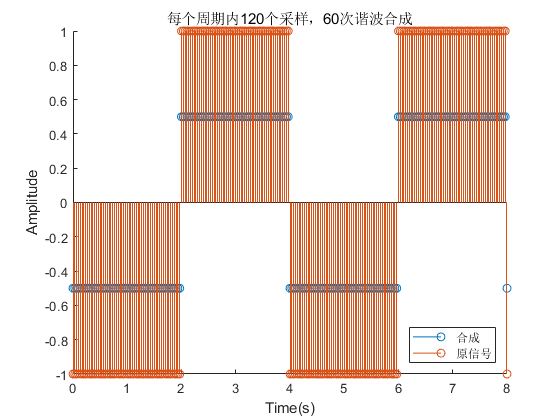


figure;
hold on;
stem(0:(T/N2):T_len, sum(dfs2(1:max_order, :), 1));
stem(0:(T/N2):T_len, sample2);
xlabel("Time(s)");
ylabel("Amplitude");
title("每个周期内120个采样，60次谐波合成");
legend(["合成", "原信号"], "Location", "southeast");
hold off;

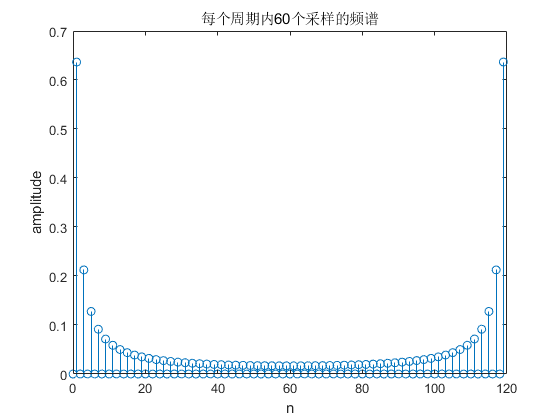


figure;
stem(0:N2-1, sqrt(a_k2.^2 + b_k2.^2));
title("每个周期内60个采样的频谱");
xlabel("n");
ylabel("amplitude");

## jagged wave

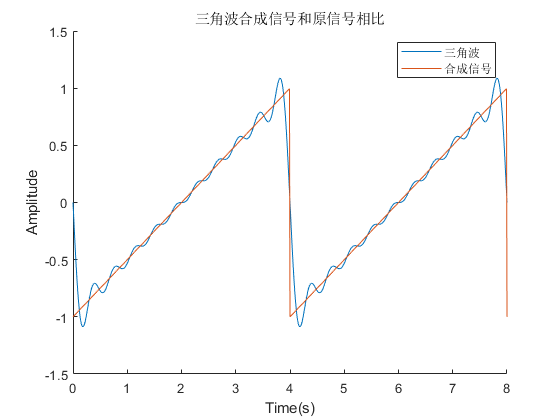

T = 8;
t = 0:0.01:T;
jaggedw = jagged_wave(t);
max_order = 20;
a_k = zeros([1, max_order]);
b_k = zeros([1, max_order]);
jagged_fourier = zeros([max_order, length(t)]);

a0 = integral(@jagged_wave, 0, T)/T;
for k = 1:max_order
    a_func = @(t)(jagged_wave(t).*cos(k*2*pi/T*t));
    b_func = @(t)(jagged_wave(t).*sin(k*2*pi/T*t));
    a_k(k) = (2/T) * integral(a_func, 0, T);
    b_k(k) = (2/T) * integral(b_func, 0, T);
end

for i = 1:length(t)
    for j = 1:max_order
        jagged_fourier(j, i) = a_k(j)*cos(j*2*pi/T*t(i)) + b_k(j)*sin(j*2*pi/T*t(i));
    end
end

figure;
hold on;
plot(t, sum(jagged_fourier, 1));
plot(t, jaggedw);
xlabel("Time(s)");
ylabel("Amplitude");
title("三角波合成信号和原信号相比");
legend(["三角波", "合成信号"]);
hold off;